clear all, close all, clc

addpath("time")
addpath("ephemeris")

AU = astroConstants(2);
muSun = astroConstants(4);

SPITZER NEOs DATA

spitzerNEOs_data = readtable('spitzerneos.csv');

a1 = table2array(spitzerNEOs_data(1,5))*AU;
T = 2*pi*sqrt(a1^3/muSun);           % Orbital Period [s]

coe1 = [a1;
        table2array(spitzerNEOs_data(1,5))*AU;]

EROS

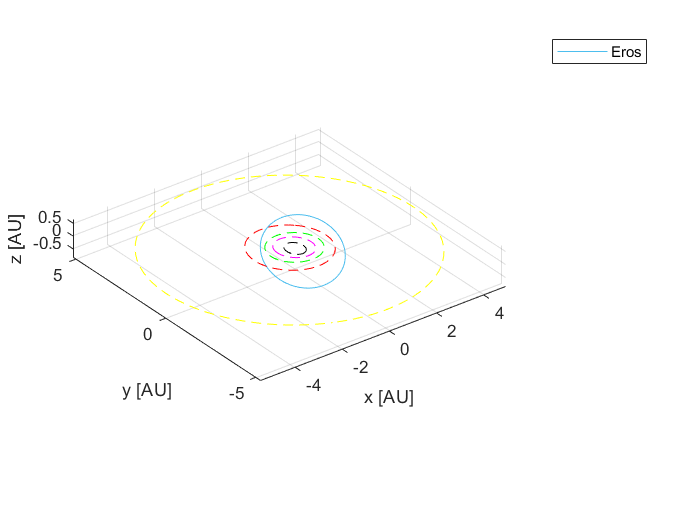

[r_eros, v_eros, eph_eros] = extraxtion_from_jpl_horizon('433_eros_jpl_horizon.txt');

figure('Name','Eros')
plot_planets(eph_eros.mjd2000_start)
hold on

% Plotting Eros
h_ER = plot3(r_eros(:,1)./AU, r_eros(:,2)./AU , r_eros(:,3)./AU );
xlabel('x [AU]'); ylabel('y [AU]');  zlabel('z [AU]'); 
grid on; axis equal; legend([h_ER], 'Eros')

APOPHIS

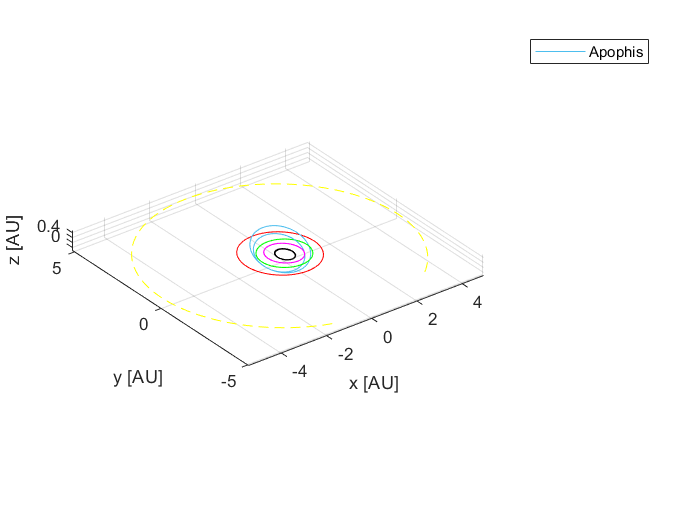

[r_apophis, v_apophis, eph_apophis] = extraxtion_from_jpl_horizon('99942_Apophis_jpl_horizon.txt');

figure('Name','Apophis')
plot_planets(eph_apophis.mjd2000_start, eph_apophis.mjd2000_end)
hold on

% Plotting Apophis
h_AP = plot3(r_apophis(:,1)./AU, r_apophis(:,2)./AU , r_apophis(:,3)./AU );
xlabel('x [AU]'); ylabel('y [AU]');  zlabel('z [AU]'); 
grid on; axis equal; legend([h_AP], 'Apophis')

89959

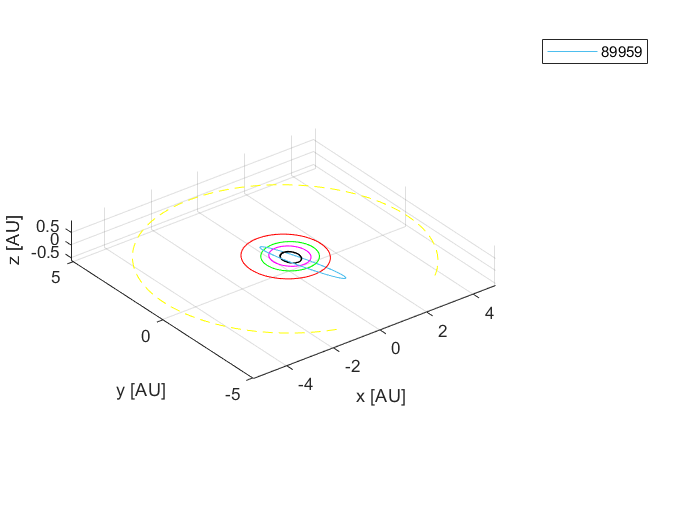

[r_89959, v_89959, eph_89959] = extraxtion_from_jpl_horizon('89959_jpl_horizon.txt');

figure('Name','89959')
plot_planets(eph_89959.mjd2000_start, eph_89959.mjd2000_end)
hold on

% Plotting Apophis
h_89959 = plot3(r_89959(:,1)./AU, r_89959(:,2)./AU , r_89959(:,3)./AU );
xlabel('x [AU]'); ylabel('y [AU]');  zlabel('z [AU]'); 
grid on; axis equal; legend([h_89959], '89959')

ALL TOGHETER NOW

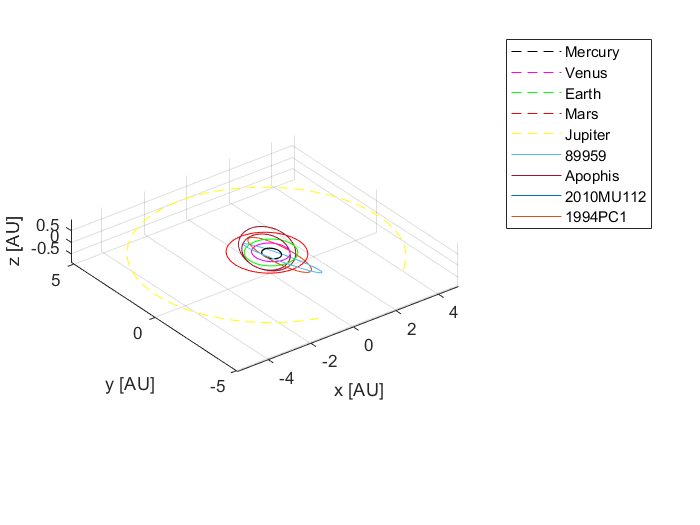

[r_apophis, v_apophis, eph_apophis] = extraxtion_from_jpl_horizon('99942_Apophis_jpl_horizon.txt');
[r_89959, v_89959, eph_89959] = extraxtion_from_jpl_horizon('89959_jpl_horizon.txt');
[r_2010MU112, v_2010MU112, eph_2010MU112] = extraxtion_from_jpl_horizon('2010MU112_jpl_horizon.txt');
[r_1994PC1, v_1994PC1, eph_1994PC1] = extraxtion_from_jpl_horizon('1994PC1_jpl_horizon.txt');
figure('Name','PHA')
[h_planets, EA] = plot_planets(eph_89959.mjd2000_start, eph_89959.mjd2000_end, length(r_apophis));
hold on

% Plotting Apophis
h_89959 = plot3(r_89959(:,1)./AU, r_89959(:,2)./AU , r_89959(:,3)./AU );
h_AP = plot3(r_apophis(:,1)./AU, r_apophis(:,2)./AU , r_apophis(:,3)./AU );
h_2010MU112 = plot3(r_2010MU112(:,1)./AU, r_2010MU112(:,2)./AU , r_2010MU112(:,3)./AU );
h_1994PC1 = plot3(r_1994PC1(:,1)./AU, r_1994PC1(:,2)./AU , r_1994PC1(:,3)./AU );
xlabel('x [AU]'); ylabel('y [AU]');  zlabel('z [AU]'); 
grid on; axis equal;
legend([h_planets.ME,h_planets.VE,h_planets.EA,h_planets.MA,h_planets.JU,...
    h_89959,h_AP,h_2010MU112, h_1994PC1],...
    'Mercury', 'Venus', 'Earth', 'Mars', 'Jupiter',...
    '89959','Apophis','2010MU112','1994PC1')

[min_MOID_AP, date_min_MOID_AP] = MOID(r_apophis, EA.r, eph_apophis.date_vect);

min_moid = 1.5229e-04

date_min_moid =         2028          11          29           0           0           0
